%Gantry Crane
clear;
clc;

%Define Knowns
M = 50; %mass of cart in kg
m = 10; %mass of load in kg
l = 15; %lenght of crane in meters
g = 9.81; %gravity constant

% Consant Force Parameters
tf = 70; %final time for force
ts = tf/2; %switch time
f = 4; % force in Newtons

%Linear System State Space Model

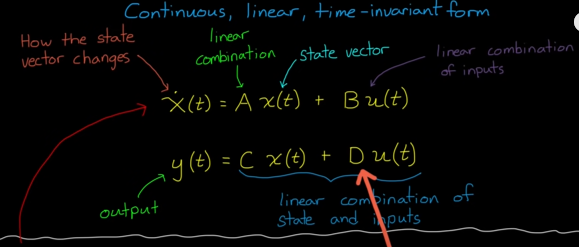

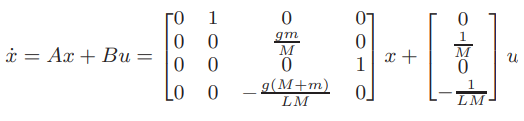


A = [0 1 0 0; 0 0 g*m/M 0 ; 0 0 0 1 ; 0 0 -1*(g*(M+m))/(l*M) 0]

A =          0    1.0000         0         0
         0         0    1.9620         0
         0         0         0    1.0000
         0         0   -0.7848         0


B = [0;1/M;0;-1/(l*M)]

B =          0
    0.0200
         0
   -0.0013


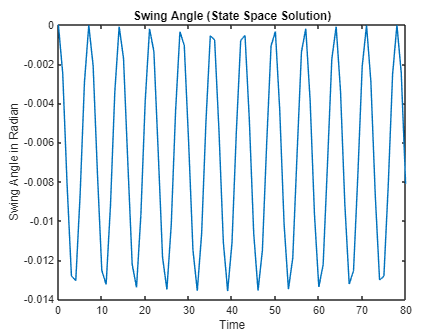

C = [1,1,1,1];
D = 0;
[t, x] = ode45(@(t,x) odeFun(t,x,A,B,f), 0:1:80, [0; 0;0;0]);
plot(0:1:80,x(:,3))
title("Swing Angle (State Space Solution)")
xlabel("Time")
ylabel("Swing Angle in Radian")

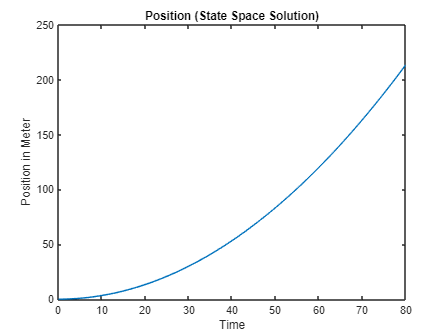

plot(0:1:80,x(:,1))
title("Position (State Space Solution)")
xlabel("Time")
ylabel("Position in Meter")

  function dxdt = odeFun(t,x,A,B,f)
    u = f; % for step input
    dxdt = A*x+B*f; % simply write the equation
  end
  